# Create Fast R-CNN Object Detection Network

This example builds upon the [Create R-CNN Object Detection Network](docid:vision_ug#mw_b8c7f0cf-790a-408e-8e52-dc76f4a4a1c6) example above. It transforms a pretrained ResNet-50 network into a Fast R-CNN object detection network by adding an ROI pooling layer and a bounding box regression layer. The Fast R-CNN network can then be trained using `trainFastRCNNObjectDetector`.

## Create R-CNN Network

Start by creating an R-CNN network that forms the basis of Fast R-CNN. The [Create R-CNN Object Detection Network](docid:vision_ug#mw_b8c7f0cf-790a-408e-8e52-dc76f4a4a1c6) example explains this section of code in detail.

% Load pretrained ResNet-50.
net = resnet50;
lgraph = layerGraph(net);

% Remove the the last 3 layers from ResNet-50. 
layersToRemove = {
    'fc1000'
    'fc1000_softmax'
    'ClassificationLayer_fc1000'
    };
lgraph = removeLayers(lgraph, layersToRemove);

% Specify the number of classes the network should classify.
numClasses = 2;
numClassesPlusBackground = numClasses + 1;

% Define new classification layers.
newLayers = [
    fullyConnectedLayer(numClassesPlusBackground, 'Name', 'rcnnFC')
    softmaxLayer('Name', 'rcnnSoftmax')
    classificationLayer('Name', 'rcnnClassification')
    ];

% Add new layers.
lgraph = addLayers(lgraph, newLayers);

% Connect the new layers to the network. 
lgraph = connectLayers(lgraph, 'avg_pool', 'rcnnFC');

## Add Bounding Box Regression Layer

Add a box regression layer to learn a set of box offsets to apply to the region proposal boxes. The learned offsets transform the region proposal boxes so that they are closer to the original ground truth bounding box. This transformation helps improve the localization performance of Fast R-CNN.

The box regression layers are composed of a fully connected layer followed by an R-CNN box regression layer. The fully connected layer is configured to output a set of 4 box offsets for each class. The background class is excluded because the background bounding boxes are not refined.

% Define the number of outputs of the fully connected layer.
numOutputs = 4 * numClasses;

% Create the box regression layers.
boxRegressionLayers = [
    fullyConnectedLayer(numOutputs,'Name','rcnnBoxFC')
    rcnnBoxRegressionLayer('Name','rcnnBoxDeltas')
    ];

% Add the layers to the network
lgraph = addLayers(lgraph, boxRegressionLayers);

The box regression layers are typically connected to same layer the classification branch is connected to.

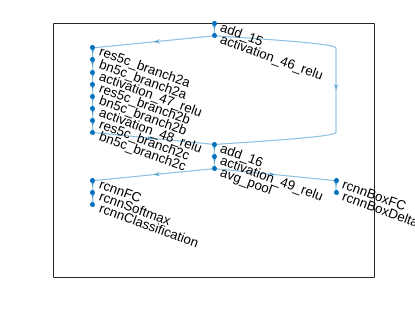

% Connect the regression layers to the layer named 'avg_pool'.
lgraph = connectLayers(lgraph,'avg_pool','rcnnBoxFC');

% Display the classification and regression branches of Fast R-CNN.
figure
plot(lgraph)
ylim([-5 16])

## Add ROI Max Pooling Layer

The next step is to choose which layer in the network to use as the feature extraction layer. This layer will be connected to the ROI max pooling layer which will pool features for classifying the pooled regions. Selecting a feature extraction layer requires empirical evaluation. For ResNet-50, a typical feature extraction layer is the output of the 4-th block of convolutions, which corresponds to the layer named activation40_relu.

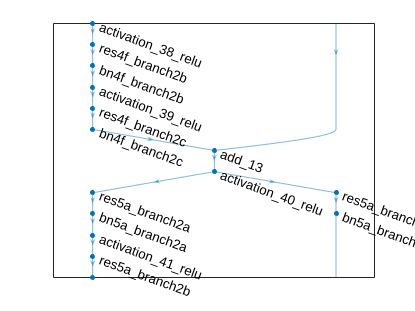

featureExtractionLayer = 'activation_40_relu';

figure
plot(lgraph)
ylim([30 42])

In order to insert the ROI max pooling layer, first disconnect the layers attached to the feature extraction layer: res5a_branch2a and res5a_branch1.

% Disconnect the layers attached to the selected feature extraction layer.
lgraph = disconnectLayers(lgraph, featureExtractionLayer,'res5a_branch2a');
lgraph = disconnectLayers(lgraph, featureExtractionLayer,'res5a_branch1');

% Add ROI max pooling layer.
outputSize = [14 14]

outputSize =     14    14


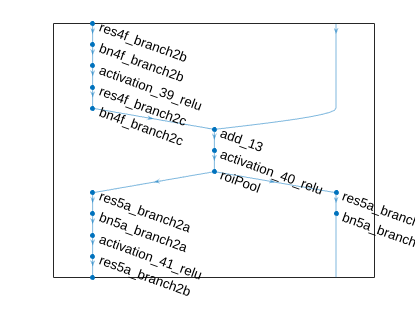

roiPool = roiMaxPooling2dLayer(outputSize,'Name','roiPool');

lgraph = addLayers(lgraph, roiPool);

% Connect feature extraction layer to ROI max pooling layer.
lgraph = connectLayers(lgraph, 'activation_40_relu','roiPool/in');

% Connect the output of ROI max pool to the disconnected layers from above.
lgraph = connectLayers(lgraph, 'roiPool','res5a_branch2a');
lgraph = connectLayers(lgraph, 'roiPool','res5a_branch1');

% Show the result after adding and connecting the ROI max pooling layer.
figure
plot(lgraph)
ylim([30 42])

% Define anchor boxes.
anchorBoxes = [
    16 16
    32 16
    16 32]

anchorBoxes =     16    16
    32    16
    16    32



%Create the region proposal layer.
proposalLayer = regionProposalLayer(anchorBoxes, 'Name','regionProposal');
lgraph = addLayers(lgraph, proposalLayer);

%Number of anchor boxes.
numAnchors = size(anchorBoxes, 1);

%Number of feature maps in coming out of the feature extraction layer.
numFilters = 1024;
rpnLayers = [
    convolution2dLayer(3, numFilters, 'Padding', [1 1], 'Name', 'rpnConv3x3')
    reluLayer('Name', 'rpnRelu')
    ]

rpnLayers =   2×1 Layer array with layers:

     1   'rpnConv3x3'   Convolution   1024 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     2   'rpnRelu'      ReLU          ReLU

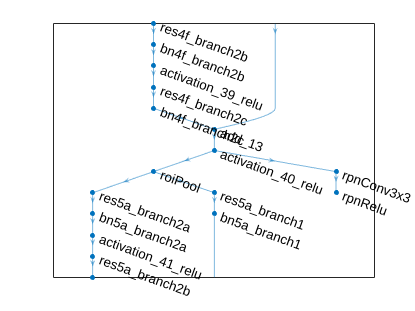


lgraph = addLayers(lgraph, rpnLayers);

%Connect to RPN to feature extraction layer.
lgraph = connectLayers(lgraph, featureExtractionLayer, 'rpnConv3x3');

figure
plot(lgraph)
ylim([30 42])

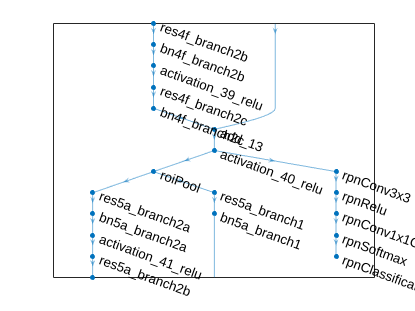


%Add RPN classification layers.
rpnClsLayers = [
    convolution2dLayer(1, numAnchors*2, 'Name', 'rpnConv1x1ClsScores')
    rpnSoftmaxLayer('Name', 'rpnSoftmax')
    rpnClassificationLayer('Name', 'rpnClassification')
    ];
lgraph = addLayers(lgraph, rpnClsLayers);

%Connect the classification layers to the RPN network.
lgraph = connectLayers(lgraph, 'rpnRelu', 'rpnConv1x1ClsScores');

figure
plot(lgraph)
ylim([30 42])

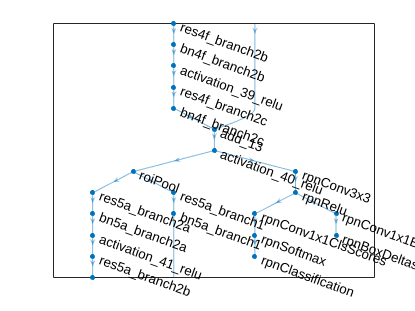


%Add RPN regression layers.
rpnRegLayers = [
    convolution2dLayer(1, numAnchors*4, 'Name', 'rpnConv1x1BoxDeltas')
    rcnnBoxRegressionLayer('Name', 'rpnBoxDeltas')
    ];

lgraph = addLayers(lgraph, rpnRegLayers);

%Connect the regression layers to the RPN network.
lgraph = connectLayers(lgraph, 'rpnRelu', 'rpnConv1x1BoxDeltas');

figure
plot(lgraph)
ylim([30 42])

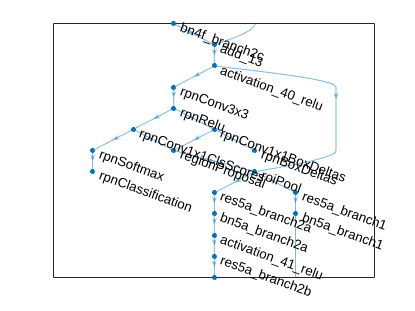


%Connect region proposal network.
lgraph = connectLayers(lgraph, 'rpnConv1x1ClsScores', 'regionProposal/scores');
lgraph = connectLayers(lgraph, 'rpnConv1x1BoxDeltas', 'regionProposal/boxDeltas');

%Connect region proposal layer to roi pooling.
lgraph = connectLayers(lgraph, 'regionProposal', 'roiPool/roi');

figure
plot(lgraph)
ylim([30 42])

Finally, connect the ROI input layer to the second input of the ROI max pooling layer.

% Add ROI input layer.
% roiInput = roiInputLayer('Name','roiInput');
% lgraph = addLayers(lgraph, roiInput);
% 
% Connect ROI input layer to the 'roi' input of the ROI max pooling layer.
% lgraph = connectLayers(lgraph, 'roiInput','roiPool/roi');
% 
% Show the resulting faster adding and connecting the ROI input layer.
% figure
% plot(lgraph)
% ylim([30 42])

The network is ready to be trained using `trainFastRCNNObjectDetector`.

*Copyright 2018 The MathWorks, Inc.*